# Template of Manipulator Short project: Skull tumor surgery

Authors: 

Team:  

Shared Link with the teacher: 

I spect: 1) Pdf file, 2) Videos demostrating your successful task and your mlx file.

Notes. For better undestanding you can split the videos in the meaninful task.

Remember use the options of serial/link plot: 

'workspace' for centering in the surgery task

'zoom' ...  nice puma ratio aspect

'trail'  .. to see the trajectory

etc..

See all at:

>> help SerialLink/plot

## The Robotic environment (10%)

Think that later on the enviroment will move to any place in a Univers Reference Frame {U}

Use: 'c = uisetcolor' to chose your prefered colors

### Operating table.

 It can be raised, lowered, and tilted in any direction, and an  auxiliary table for the tools. Define: Vertices and Faces and use  'patch'  functions to model it. See help patch to find and example.

Think that later on the enviroment will move to any place in a Univers Reference Frame {U}

**Expected results**

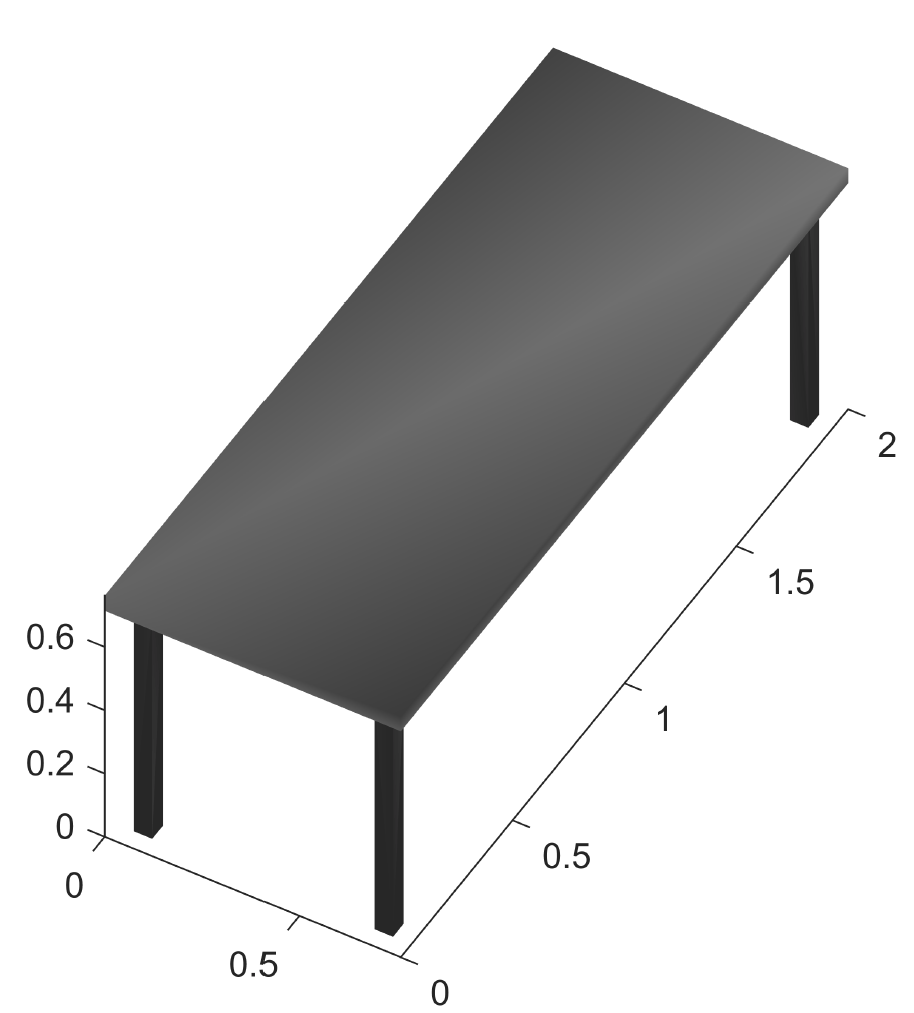

clear
clf
minXMesa = 0

minXMesa = 0

minYMesa = 0

minYMesa = 0

maxXMesa = 2

maxXMesa = 2

maxYMesa = 0.75

maxYMesa = 0.7500

minZMesa = 0.5

minZMesa = 0.5000

maxZMesa = 0.6

maxZMesa = 0.6000

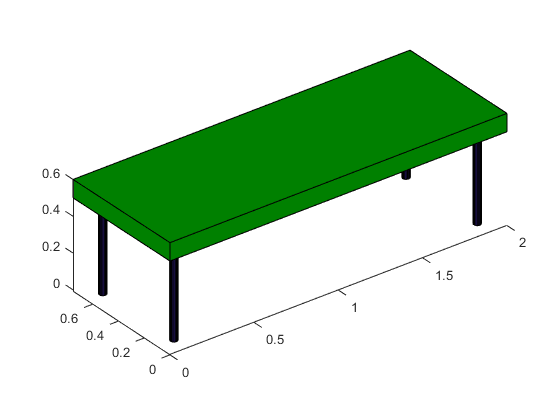

vM = [minXMesa minYMesa minZMesa; minXMesa maxYMesa minZMesa; maxXMesa maxYMesa minZMesa; maxXMesa minYMesa minZMesa;minXMesa minYMesa maxZMesa; minXMesa maxYMesa maxZMesa; maxXMesa maxYMesa maxZMesa; maxXMesa minYMesa maxZMesa];
fM = [1 2 6 5;2 3 7 6;3 4 8 7;4 1 5 8;1 2 3 4;5 6 7 8];
view(3)

patch('Faces',fM,'Vertices',vM,'FaceColor',[0 0.5 0])

r = 0.02;
[X,Y,Z] = cylinder(r);
h = 0.6;
Z = Z*h-0.01;

hold on
surf(X+0.1,Y+0.1,Z)
surf(X+0.1,Y+0.65,Z)
surf(X+1.9,Y+0.1,Z)
surf(X+1.9,Y+0.65,Z)
axis equal

### 3D model of a human body 

Situate the human model on the operating table. 

**Expected results**

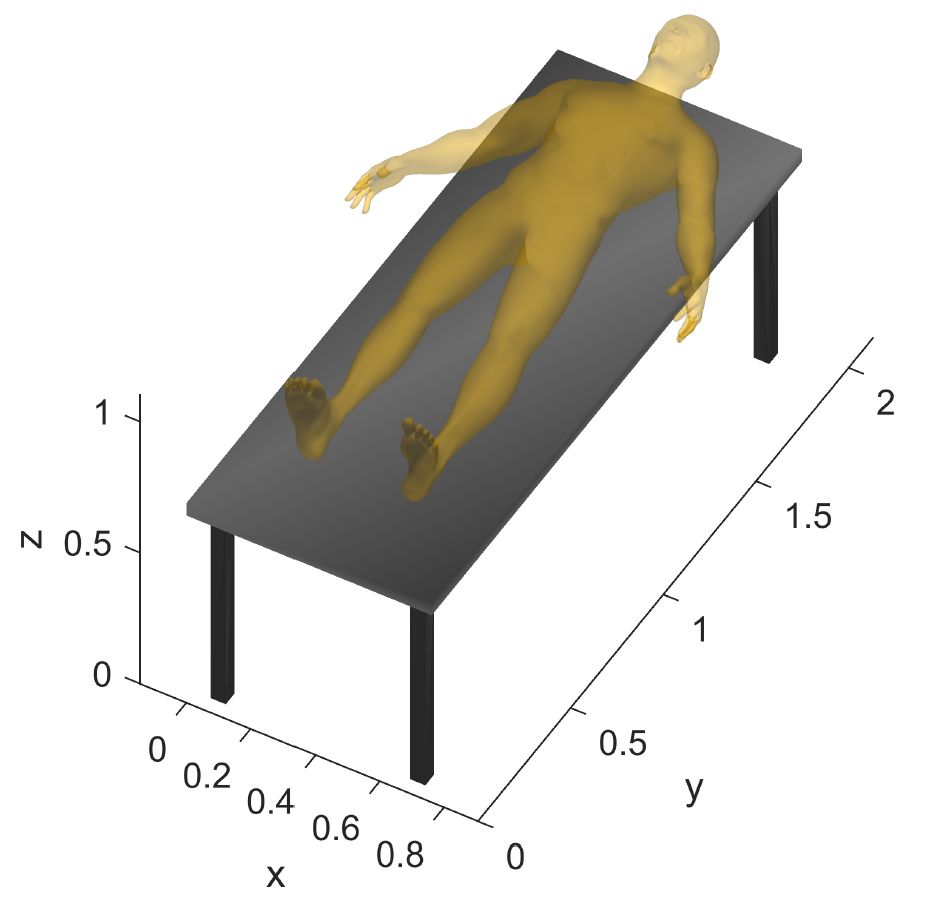

load('F_V_HumanBody.mat')
view(3)
Vh(:,4) = 1;
T_C_0 = transl(0.45,0.375,0.77)*trotz(-pi/2)*trotx(-pi/2)

T_C_0 =          0         0    1.0000    0.4500
   -1.0000         0         0    0.3750
         0   -1.0000         0    0.7700
         0         0         0    1.0000


Vh = T_C_0 * Vh'

Vh =     1.7610    1.7649    1.7738    1.7706    1.7789    1.7786    1.7805    1.7844    1.7881    1.7919    1.7961    1.8000    1.7864    1.7948    1.7972    1.8035    1.8068    1.8125    1.8165    1.8214    1.8262    1.8301    1.8359    1.8312    1.8206    1.8419    1.8245    1.8316    1.8383    1.8167    1.8452    1.8084    1.8042    1.8121    1.8100    1.7996    1.7909    1.7894    1.8019    1.7879    1.7792    1.7787    1.7799    1.8131    1.8159    1.8039    1.7922    1.7693    1.7580    1.7589
    0.4893    0.5018    0.4941    0.4857    0.4896    0.4833    0.4987    0.4912    0.5016    0.4930    0.5037    0.4948    0.4831    0.4840    0.4743    0.4853    0.4753    0.4869    0.4768    0.4889    0.4789    0.4912    0.4814    0.4684    0.4663    0.4710    0.5003    0.5027    0.4941    0.4983    0.4846    0.4965    0.5054    0.5068    0.4649    0.4640    0.4530    0.4637    0.4532    0.4739    0.4641    0.4743    0.4533    0.4541    0.4432    0.4425    0.4422    0.4759    0.4667    

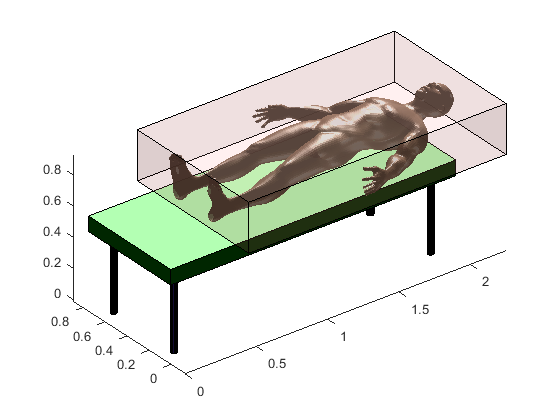

patch('Vertices',Vh(1:3,:)','Faces',Fh,'FaceColor', [0.82 0.64 0.52], 'EdgeColor' , 'none', 'FaceAlpha', 0.8)
axis equal
light('Position',[3,3,3]);
view(3)
%CAJA CONTENEDORA 
minCuerpo = min(Vh');
maxCuerpo = max(Vh');
vM = [minCuerpo(1) minCuerpo(2) minCuerpo(3); minCuerpo(1) maxCuerpo(2) minCuerpo(3); maxCuerpo(1) maxCuerpo(2) minCuerpo(3); maxCuerpo(1) minCuerpo(2) minCuerpo(3);minCuerpo(1) minCuerpo(2) maxCuerpo(3); minCuerpo(1) maxCuerpo(2) maxCuerpo(3); maxCuerpo(1) maxCuerpo(2) maxCuerpo(3); maxCuerpo(1) minCuerpo(2) maxCuerpo(3)];
fM = [1 2 6 5;2 3 7 6;3 4 8 7;4 1 5 8;1 2 3 4;5 6 7 8];
view(3)

 patch('Faces',fM,'Vertices',vM,'FaceColor',[1 0 0],'FaceAlpha',0.1)

### Fiducials

The Radiology Department before to take a Computer Tomography (CT) of the brain, fix three fiducials in the head of the patient for registering purpose,  visit: [https://en.wikipedia.org/wiki/Fiducial](https://en.wikipedia.org/wiki/Fiducial)

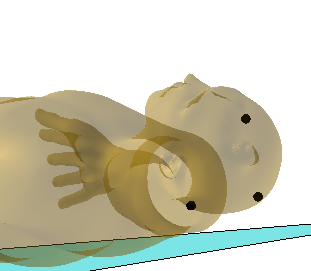

### Dicom image vs Image Reference frame {I}

Get familiar with Dicom Images, Visit: https://www.imaios.com/en/Imaios-Dicom-Viewer#!

Use a container Box of the skull  to infer the Image Reference Frame {I}

See:  6_Plot_Box_Cone.mlx and 7_Help_Image_RF_Containig_Box.fig to inspire yourselt 

**Expected results**

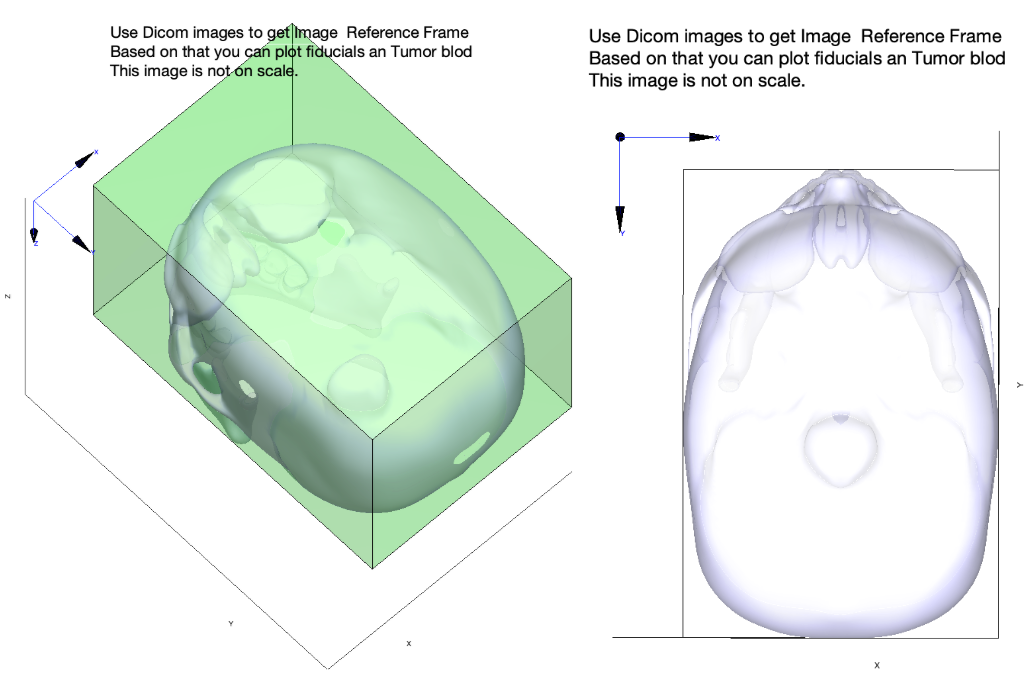

## put your code Here

clear
clf
load('F_V_Skull.mat')
view(3)
Vs(:,4) = 1;
Vs = trotz(pi) * Vs';
Vs = Vs(1:3,:)'

Vs =     0.0127    0.1141    0.0085
    0.0097    0.1154    0.0082
    0.0094    0.1149    0.0110
    0.0124    0.1136    0.0112
    0.0065    0.1165    0.0080
    0.0063    0.1159    0.0108
    0.0061    0.1152    0.0140
    0.0092    0.1142    0.0142
    0.0122    0.1130    0.0143
    0.0033    0.1172    0.0078


light('Position',[1 1 1]);
patch('Vertices',Vs,'Faces',Fs,'FaceColor', [0.5 0.5 0.5], 'EdgeColor' , 'none','FaceAlpha', 0.5)

%CAJA CONTENEDORA
minSkull = (min(Vs))

minSkull =    -0.0765   -0.1077    0.0004


maxSkull = (max(Vs))

maxSkull =     0.0765    0.1194    0.2127


minSkullX = minSkull(1)

minSkullX = -0.0765

minSkullY = minSkull(2)

minSkullY = -0.1077

minSkullZ = minSkull(3)

minSkullZ = 3.8712e-04


maxSkullX = maxSkull(1)

maxSkullX = 0.0765

maxSkullY = maxSkull(2)

maxSkullY = 0.1194

maxSkullZ = maxSkull(3)

maxSkullZ = 0.2127


v= [minSkullX minSkullY minSkullZ;maxSkullX minSkullY minSkullZ;maxSkullX maxSkullY minSkullZ;minSkullX maxSkullY minSkullZ;minSkullX minSkullY maxSkullZ;maxSkullX minSkullY maxSkullZ;maxSkullX maxSkullY maxSkullZ;minSkullX maxSkullY maxSkullZ]

v =    -0.0765   -0.1077    0.0004
    0.0765   -0.1077    0.0004
    0.0765    0.1194    0.0004
   -0.0765    0.1194    0.0004
   -0.0765   -0.1077    0.2127
    0.0765   -0.1077    0.2127
    0.0765    0.1194    0.2127
   -0.0765    0.1194    0.2127


f = [1 2 6 5;2 3 7 6;3 4 8 7;4 1 5 8;1 2 3 4;5 6 7 8]

f =      1     2     6     5
     2     3     7     6
     3     4     8     7
     4     1     5     8
     1     2     3     4
     5     6     7     8


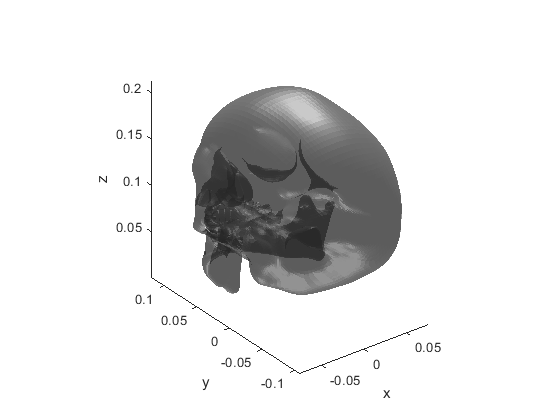

%patch('Vertices',v,'Faces',f,'FaceVertexCData',hsv(6),'FaceColor','g','FaceAlpha',0.1)
axis equal
xyzlabel

### Fiducials wrt {I}

Use the Dicom images to place the fiducial relative to Image Reference Frame {I}.

See: 5_Skull_pose_estimation.mlx and use the skull to make the exercise.

**Expected results**

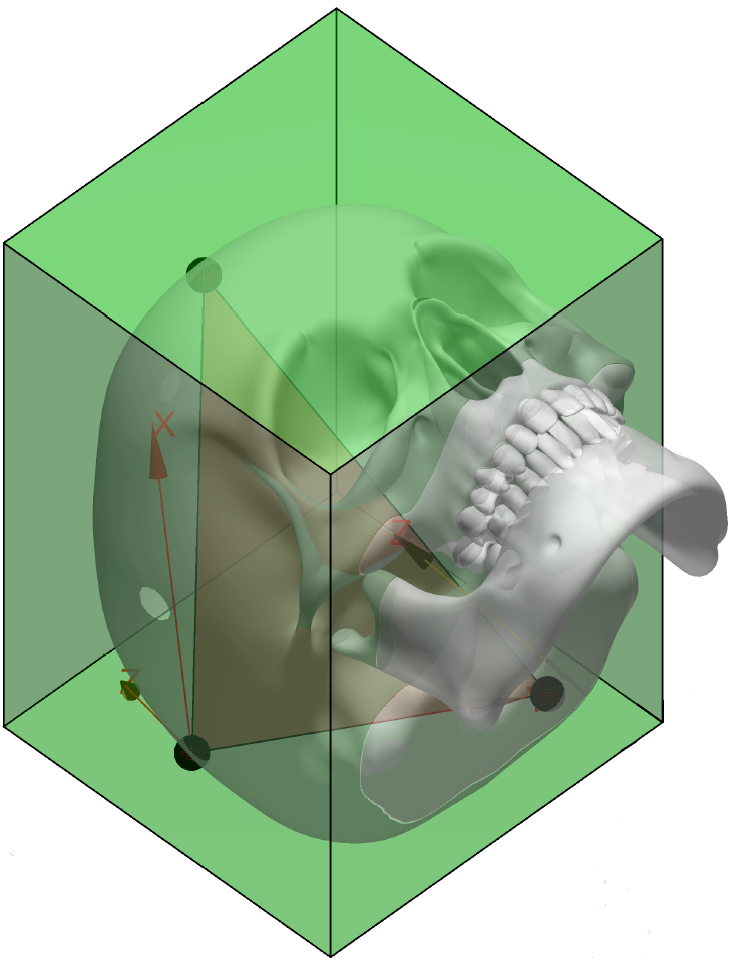

## put your code Here

pFid1 = [122, 61 , 131.6];
pFid2 = [185, 209 , 91];
pFid3 = [71, 212 , 44.8];

%MEDIDA CAJA DICOM
minXDic = 41;
maxXDic = 206;
minYDic = 27;
maxYDic = 234;
minZDic = 0;
maxZDic = 122 * 1.4;

minHeadDicom = [minXDic,minYDic,minZDic];
maxHeadDicom = [maxXDic,maxYDic,maxZDic];

pFid = [pFid1;pFid2;pFid3];
% PROP DICOM -> SKULL
minSkullZ = 0.072

minSkullZ = 0.0720

minSkull(3) = 0.072

minSkull =    -0.0765   -0.1077    0.0720


dicomToSkull = (maxSkull-minSkull) ./ (maxHeadDicom-minHeadDicom)

dicomToSkull =     0.0009    0.0011    0.0008


dicomToSkullX = (maxSkullX-minSkullX) / (maxXDic - minXDic)

dicomToSkullX = 9.2727e-04

dicomToSkullY = (maxSkullY-minSkullY) / (maxYDic - minYDic)

dicomToSkullY = 0.0011

dicomToSkullZ = (maxSkullZ-minSkullZ) / (maxZDic - minZDic)

dicomToSkullZ = 8.2350e-04

dicomToSkull2 = [dicomToSkullX,dicomToSkullY,dicomToSkullZ]

dicomToSkull2 =     0.0009    0.0011    0.0008


pFidS = pFid .* dicomToSkull

pFidS =     0.1131    0.0669    0.1084
    0.1715    0.2293    0.0749
    0.0658    0.2326    0.0369


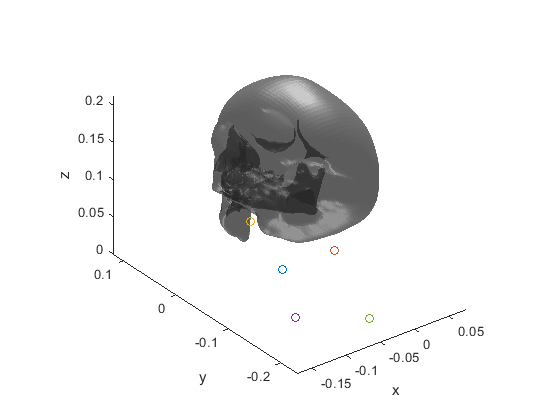

maxDicomSkull = maxHeadDicom .* dicomToSkull;
minDicomSkull = minHeadDicom .* dicomToSkull;

minDicomSkullAux = minDicomSkull';
minDicomSkullAux(4,:) = 1;
minDicomSkullAux = trotz(pi) * minDicomSkullAux;
minDicomSkullAux = minDicomSkullAux(1:3,:);
hold on
scatter3(minDicomSkullAux(1),minDicomSkullAux(2),minDicomSkullAux(3))
scatter3(minDicomSkull(1),minDicomSkullAux(2),minDicomSkullAux(3))
T_D_S = transl(0)*trotz(pi);

pFidS = pFidS';
pFidS(4,:) = 1;
pFidS1 = T_D_S * pFidS;
pFidS1 = pFidS1(1:3,:)';
hold on
scatter3(pFidS1(1,1),pFidS1(1,2),pFidS1(1,3))
scatter3(pFidS1(2,1),pFidS1(2,2),pFidS1(2,3))
scatter3(pFidS1(3,1),pFidS1(3,2),pFidS1(3,3))

### Tumor points wrt {I}

Use the Dicom images to get the points of the outer perimeter of the tumor relative to Image Reference Frame {I}.

You can simplify the tumor information by defining the center of mass and estimate an equivalent diameter.

**Expected results**

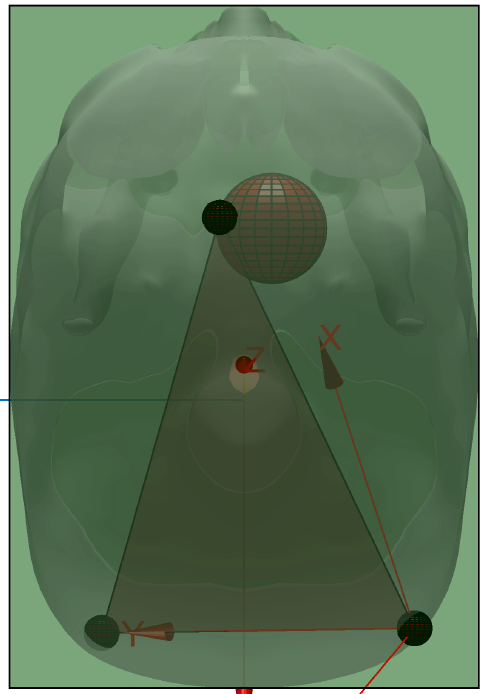

%% put your code Here

### Fiducials and Tumor wrt Human Reference Frame

Place fiducial and tumor in the head of the human. You will have to re-do the containing box secction.

**Expected results**

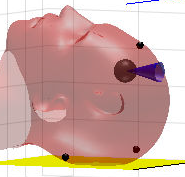

## *First approach (10%)  *

*Asume that the ZX plane of the Robot is aligned with the plane of symmetry of the human body.*

### Robot manipulator

Consider  the best position of manipulator to be nearby the operating table to warranty that the head is in the reachable work space. Use a Puma 560. Use p560.teach to play.

Use: p560.base & p560.tool to locate the Puma and add the tools.

**Expected results**

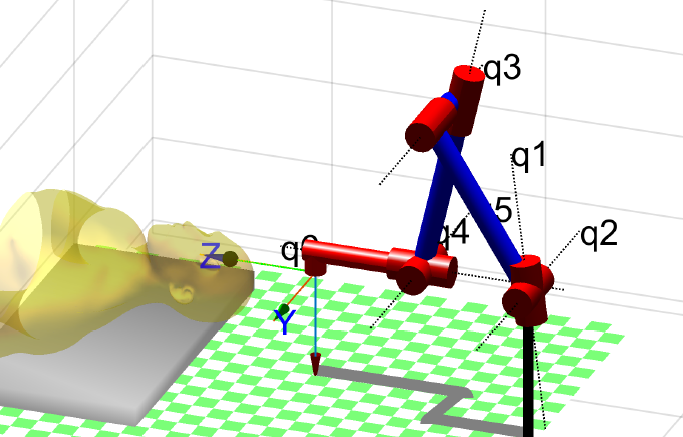

%% put your code Here

### Reference Frames

Display all necessary reference frame. Use best scale to see it.

- {U} Univers [0 0 0]

- {R} Robot

- {I} Image

- {Tb} Table_body

- {Tt} Table tool

- {EE} End Efector

- others

- ...

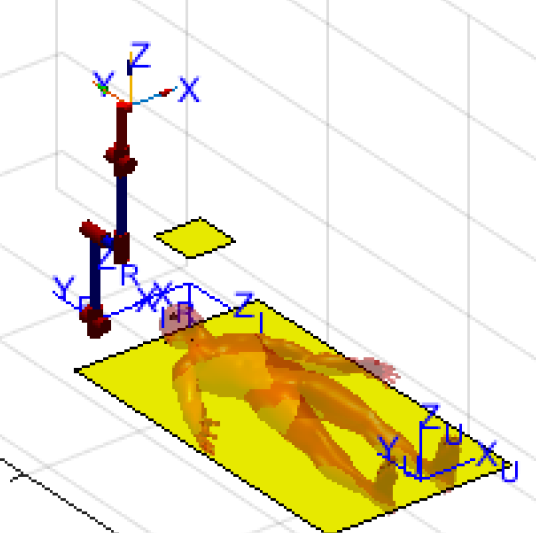

%% put your code Here

### Transformations

Enumerate the transformation you will need.

%% put your code Here

### Tumor points in Robot Frame.

Remember the Transform compound exercise

%% put your code Here


F1D =     5.7726
    9.1591
    0.6575


F2D =     5.8232
    9.2750
    0.6616


F3D =     5.7489
    9.2581
    0.8134


## *Second approach: ( 25%)*

Modify your code  to repeat the exercise if  the table with the patient is given as happend in the Rosa video.

To know the head relative pose with respect to the Puma Robot ...

*See:  **‘4_Sckeching_Key_ideas_students.mlx’ , ‘5_Skull_pose estimation.mlx’ for inspiration and Second_approach_SPM.pdf*

% open('3_Second_approach_Patient_pose.fig')
open('Second_approach_Patient_Solution.fig')
F1D=[ 5.7726    9.1591    0.6575]' 
F2D= [5.8232    9.2750    0.6616]' 
F3D= [5.7489    9.2581    0.8134]' 

## Surgery (55%)

### Biospy

Prepare a script that perform a biopsy. Zoom in the scene and record a video with the best view.

Use a tool that has the following Transformation: transl(0.05 0 0.25)

Let us see the 'trail' option of plot to visualize the trajectory.

%% put your code Here

### Trepanation

Prepare a script that perform trepanation. Zoom in the scene and record a video with the best view.

Use a tool that has the following Transformation: transl(0 0 0.2)

Let us see the 'trail' option of plot to visualize the trajectory. Place a 45º cone on top of the trepanation to better understand. See: 6_Plot_Box_Cone.mlx. You will have to scale it. Play with transparency.

%% put your code Here

### Tumor burning

Prepare a script that perform tumor burning with the laser.  Zoom in the scene and record a video with the best view.

You ought to think in an algorithm, that in order, fill up the tumor's  equivalent sphere with small burning spheres of 4m diameter.

Use a tool that has the following Transformation: transl(0 0 0.2)

%% put your code Here